Bildvergleich - Lea, Clara

R = [[1,2,3];[1,2,3]];
A = [[1,2,3];[1,2,4]];

del1

del1 = (1/ (size(A,1)*size(A,2))) * sum(sum(abs(R-A)));
disp(del1)

    0.1667



del2

del2 = sqrt((1/ (size(A,1)*size(A,2))) * sum(sum((R-A).^2)));

del3

del3 = sum(sum((A-R).^2)) / sum(sum((A+R).^2));

del4

del4 = sum(sum((A-R).^2)) / sum(sum((A-(mean(A,"all"))).^2));

del5

del5 = sum(sum(abs(A-R))) / sum(sum(abs(A)));

uniformity

uniformity = 1 - 1/2 *(sum(sum(abs(A-mean(A,'all'))))/sum(sum(abs(A))));

Paralleltomo Miriam, Daniel

### Fächerstrahltomographie

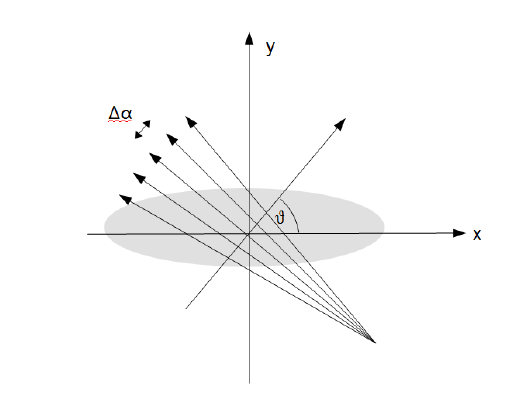

#### Parameter

- N            Zellen/Pixel pro Zeile/Spalte

- theta       Vektor mit verwendeten Winkeln

- p             Anzahl an Strahlen pro Winkel

- R            Abstand von Sender zum Mittelpunkt des Objekts

- d             Spannweite der Strahlen

- isDisp     Boolean, ob Zwischenergebnisse angezeigt werden sollen

N = 100;
theta = 0:1:359;
p = round(sqrt(2)*N);
R = 2;
d = 2*atand(1/(2*R-1));
isDisp = 0;

#### Absoptionskoeffizient

Hier kann ein beliebiger Absorptionskoeffizient erstellt werden

**Beispielsweise:**

- Beispelbilder

- Einzelne Matrizen von Hand

- Phantombilder

**Phantomgallerie:**

Matlab Funktion, die verschiedene Phantombilder erzeugen kann. Diese sind besonders zum Testen von Rekonstruktionen geeignet. 

- smooth

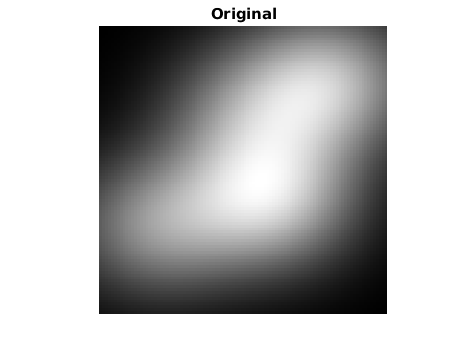

- binary

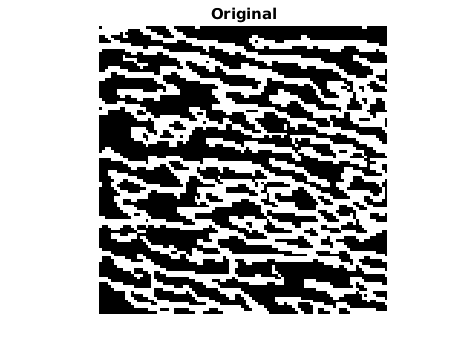

- treephases

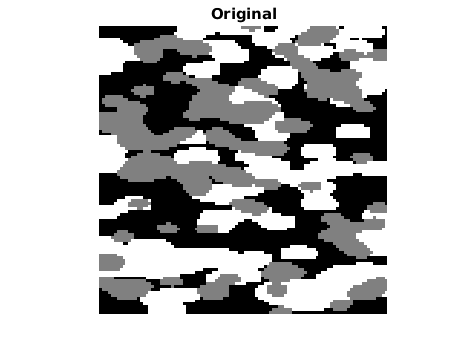

- treephasessmooth

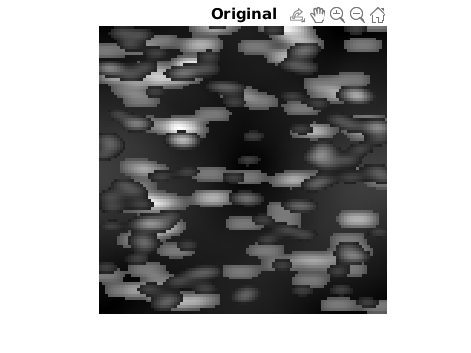

- fourphases

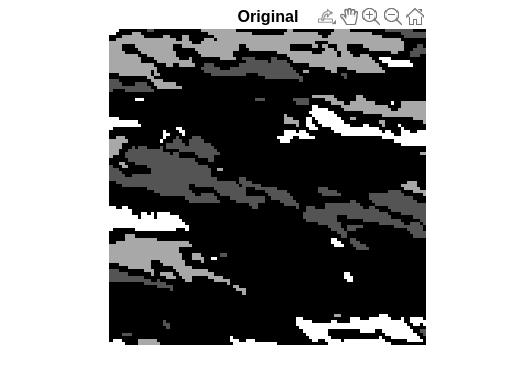

- grains

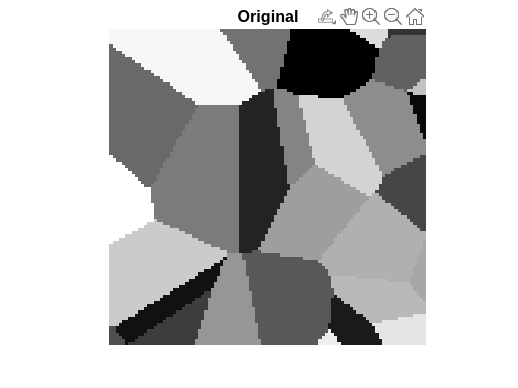

- ppower

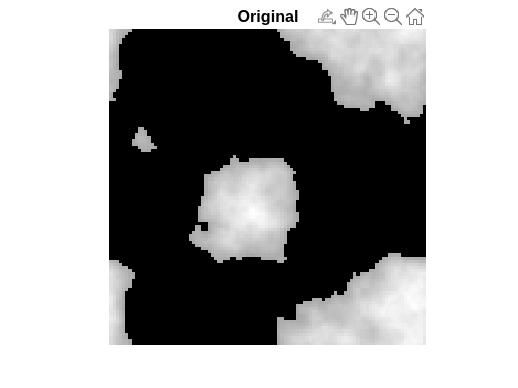

**Änderungen an *****fanbeamtomo.m:***

absCoeff = phantomgallery('smooth',N);

[A, b, x, theta, d, p] = fanbeamtomo(N,theta,p,R,d,isDisp, absCoeff);

**Relevante Rückgabewerte**

- x:  Vektor mit exakter Lösung

- A:  Koeffizientenmatrix

- b:  Vektor zur Matrix

#### Lösen des Gleichungssystemes

K = 5; % Anzahl der Iterationen

[X,info] = kaczmarz(A,b,K);

#### Anzeigen der Rekonstruktion und des Originals

figure;
imagesc(reshape(x,N,N)), colormap gray,

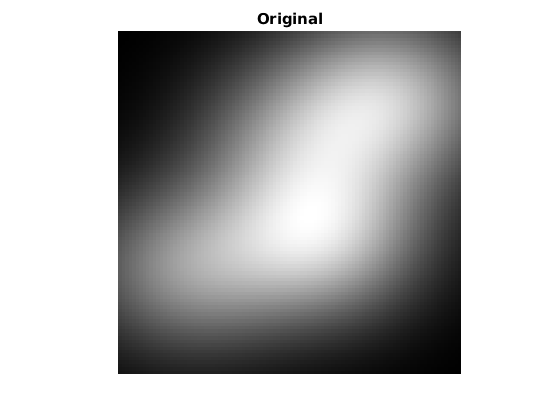

axis image off
c = caxis;
title('Original');

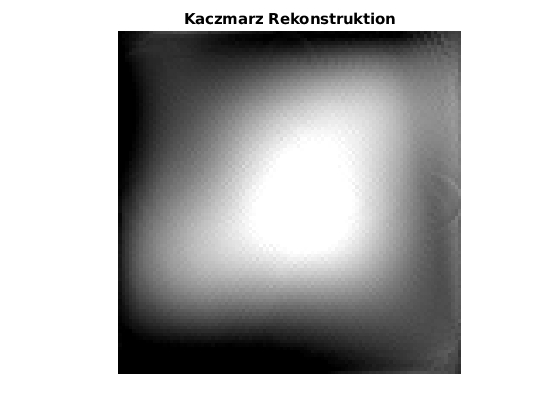

figure
imagesc(reshape(X,N,N)), colormap gray,
axis image off
caxis(c)
title('Kaczmarz Rekonstruktion')

#### Numerisches Vergleichen der Bilder

Berechnen der Vergleichswerte

[del1,del2,del3,del4,del5, uniformity] = bildvergleich(x,X);

del1:

disp(del1);

    0.1175



del2:

disp(del2);

    0.1426



del3:

disp(del3);

    0.0162



del4:

disp(del4);

    0.1947



del5:

disp(del5);

    0.2417



uniformity:

disp(uniformity);

    0.7231



#### Visuelles Vergleichen der Bilder 

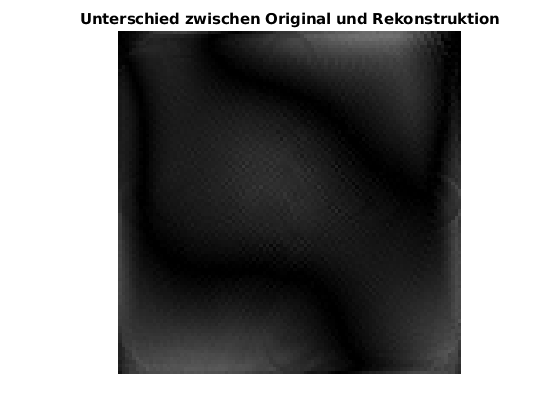

l = abs(X-x);

figure
imagesc(reshape(l,N,N)), colormap gray,
axis image off
caxis(c)
title('Unterschied zwischen Original und Rekonstruktion')